syms T V 

R = 8.314;
Ttriple = 314.06;
Tcrit = 693.65;
Pcrit = 6.03008e+6;
antA = 4.29371;
antB = 995.445;
antC = -47.869;
Pant = @(T) (10^5)*10^(antA - (antB/(T + antC)));
b = 0.0778*R*Tcrit/Pcrit;

%omega = -1 - log10(Pant(0.7*Tcrit)/Pcrit);
omega = 0.438;
k_small = 0.37464 + 1.5422*omega - 0.26992*omega^2;
alpha_T = @(T) (1 + k_small*(1 - sqrt(T./Tcrit)))^2;
a_T = @(T) (0.45724*(R^2)*(Tcrit^2)/Pcrit) * alpha_T(T);
Prb = @(T,V) R*T./(V - b) - a_T(T)/(V.*(V + b) + b*(V - b));

Trange = linspace(Ttriple,2*Tcrit,100);
Prange = Pcrit*[0.000000001,0.5,1];

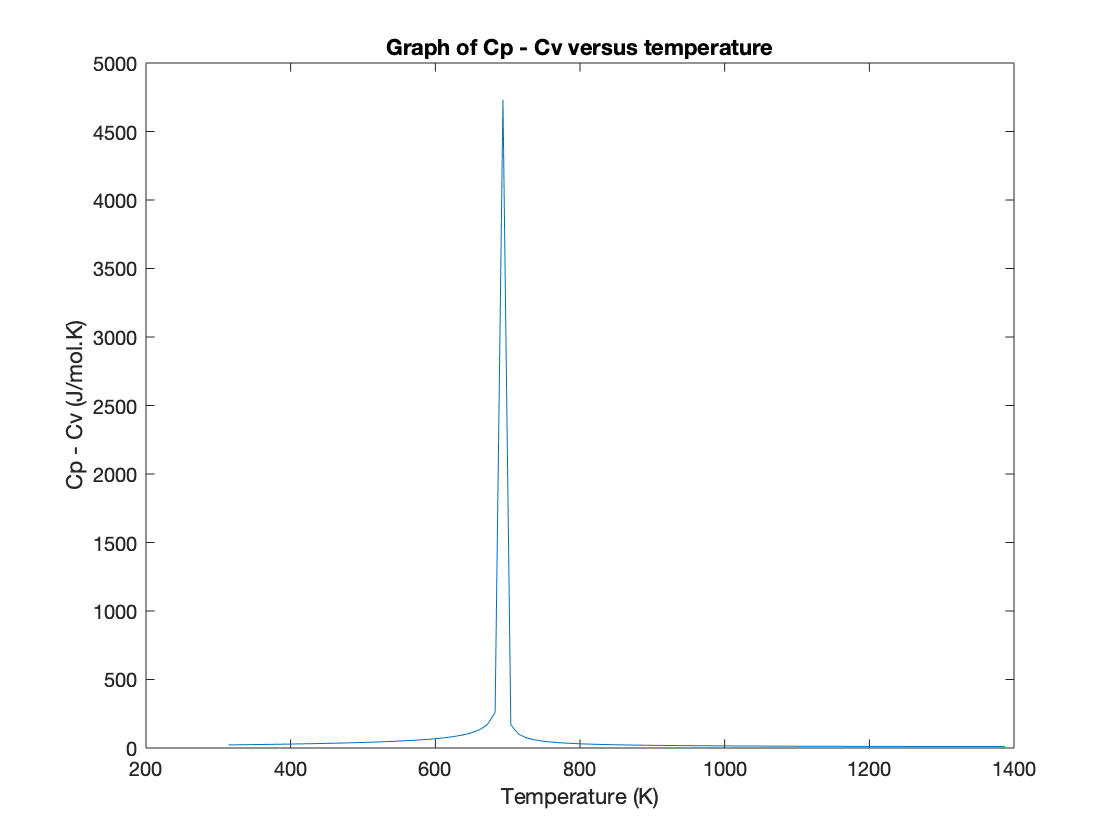

% NO 4 - Cp - Cv vs. T graph
alpha = zeros(1,length(Trange));

% doing approximation method in dvdt instead of actual diff dvdt
for i = 1:length(Trange)
    
    t_up = Trange(i) + 0.1;
    t_down = Trange(i) - 0.1;
    v1 = max(vpasolve(Prb(t_up,V) == Pcrit, V, [0 Inf]));   
    v2 = max(vpasolve(Prb(t_down,V) == Pcrit, V, [0 Inf]));

    dvdt = (v1 - v2)/(t_up - t_down);
    Vreal = max(vpasolve(Prb(Trange(i),V) == Pcrit, V, [0 Inf]));

    alpha(i) = dvdt/Vreal;
end

Varray = zeros(1,length(Trange));
kappa = zeros(1,length(Trange));

dvdp = matlabFunction(1/diff(Prb,V));

for i = 1:length(Trange)
    Vreal = max(vpasolve(Prb(Trange(i),V) == Pcrit, V, [0 Inf]));
    Varray(i) = Vreal;
    kappa(i) = (-1/Vreal)*dvdp(Trange(i),Vreal);
end

cp_cv_array = zeros(1,length(Trange));

for i = 1:length(Trange)
   cp_cv_array(i) = Trange(i)*Varray(i)*alpha(i)^2/kappa(i);
end

plot(Trange,cp_cv_array)
xlabel('Temperature (K)')
ylabel('Cp - Cv (J/mol.K)')
title('Graph of Cp - Cv versus temperature')

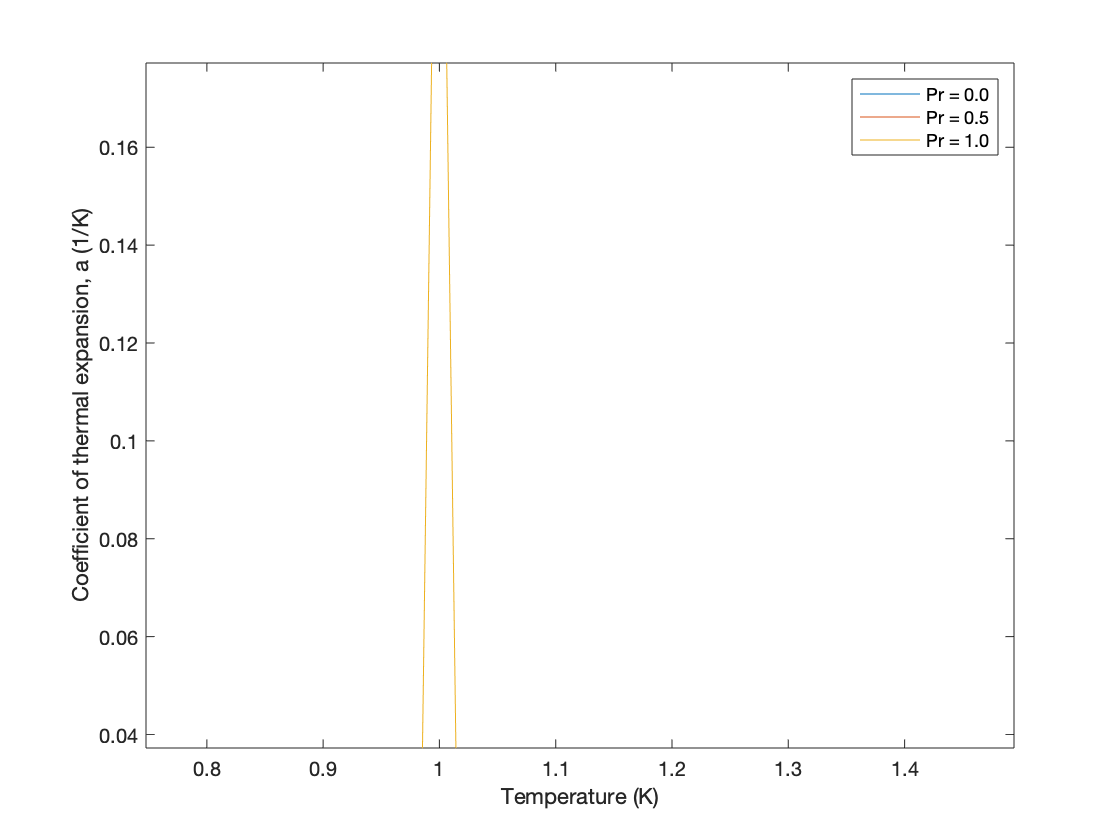

% NO 7 - thermal expansion vs. T graph
% setting up three sets of alpha w.r.t 3 diff pressure
Trange = linspace(Ttriple,2*Tcrit,100);
for j = 1:length(Prange)
    alpha = zeros(1,length(Trange));
    for i = 1:length(Trange)
        t_up = Trange(i) + 0.1;
        t_down = Trange(i) - 0.1;
        v1 = max(vpasolve(Prb(t_up,V) == Prange(j), V, [0 Inf]));   
        v2 = max(vpasolve(Prb(t_down,V) == Prange(j), V, [0 Inf]));

        dvdt = (v1 - v2)/(t_up - t_down);
        Vreal = max(vpasolve(Prb(Trange(i),V) == Prange(j), V, [0 Inf]));
 
        alpha(i) = dvdt/Vreal;
    end
    plot(Trange./Tcrit,alpha)
    hold on
    if j == 1
        alpha_P1 = alpha;
    elseif j == 2
        alpha_P2 = alpha;
    elseif j == 3
        alpha_P3 = alpha;
    end
end

xlabel('Temperature (K)')
ylabel('Coefficient of thermal expansion, a (1/K)')
%title('Graph of thermal expansion coefficient versus temperature')
legend('Pr = 0.0','Pr = 0.5','Pr = 1.0')
hold off

% setting up three sets of kappa and volume w.r.t 3 diff pressure
for j = 1:length(Prange)
    kappa = zeros(1,length(Trange));
    Varray = zeros(1,length(Trange));
    for i = 1:length(Trange)
        Vreal = max(vpasolve(Prb(Trange(i),V) == Prange(j), V, [0 Inf]));
        Varray(i) = Vreal;
        kappa(i) = (-1/Vreal)*dvdp(Trange(i),Vreal);
    end
    if j == 1
        kappa_P1 = kappa;
        Vol1 = Varray;
    elseif j == 2
        kappa_P2 = kappa;
        Vol2 = Varray;
    elseif j == 3
        kappa_P3 = kappa;
        Vol3 = Varray;
    end
end

for j = 1:length(Prange)
    cp_cv_array = zeros(1,length(Trange));
    for i = 1:length(Trange)
        if j == 1
            cp_cv_array(i) = Trange(i)*Vol1(i)*alpha_P1(i)^2/kappa_P1(i);
        elseif j == 2
            cp_cv_array(i) = Trange(i)*Vol2(i)*alpha_P2(i)^2/kappa_P2(i);
        elseif j == 3
            cp_cv_array(i) = Trange(i)*Vol3(i)*alpha_P3(i)^2/kappa_P3(i);
        end
    if j == 1
        cp_cv1 = cp_cv_array;
    elseif j == 2
        cp_cv2 = cp_cv_array;
    elseif j == 3
        cp_cv3 = cp_cv_array;
    end
    end
end

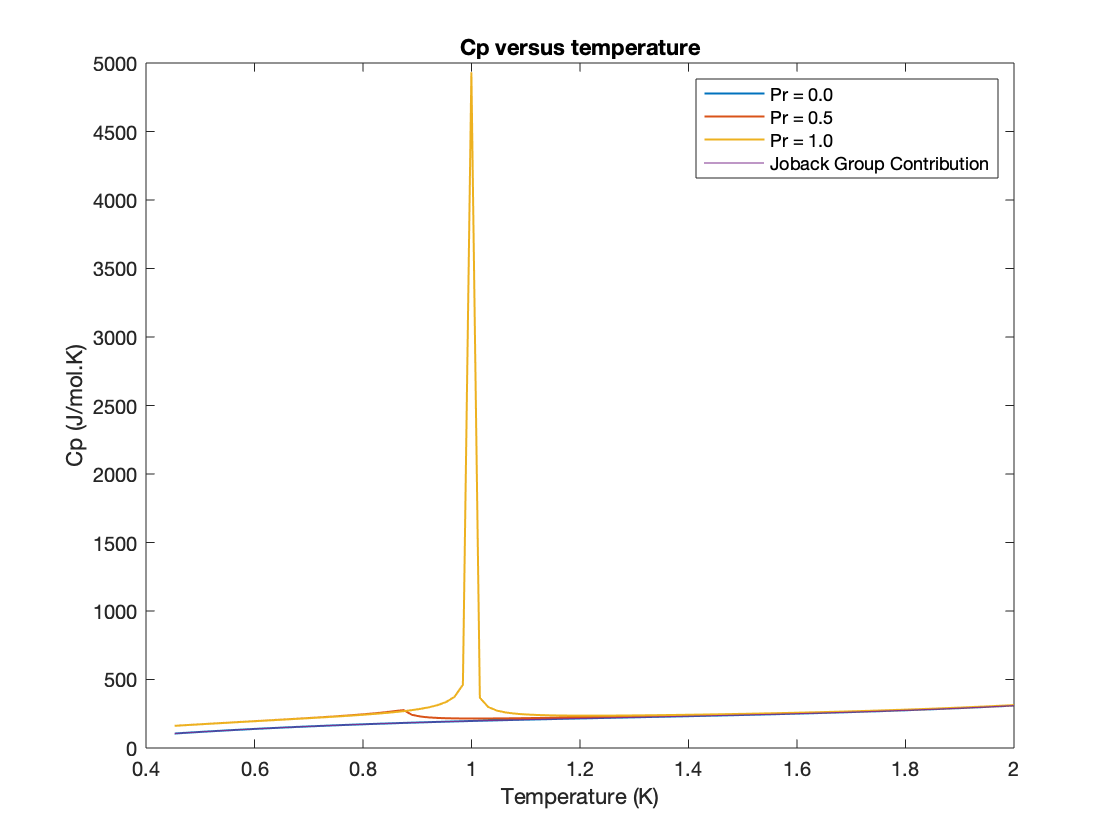

% NO 5 - Cp vs. T graph
Trange = linspace(Ttriple,2*Tcrit,100);
a_cp = -59.69;
b_cp = 0.709;
c_cp = -6.572e-4;
d_cp = 2.437e-7;
cp_star = @(T) a_cp + b_cp*T + c_cp*T.^2 + d_cp*T.^3;
cv_star = @(T) cp_star(T) - R;

dpdt = diff(Prb,T);

dpdt_secdiff = matlabFunction(diff(dpdt,T));

for j = 1:length(Prange)
    cv = zeros(1,length(Trange));
    for i = 1:length(Trange)
        if j == 1
            intgrl = @(T)- int(dpdt_secdiff(T,V),V,Vol1(i),Inf);
            cv(i) = cv_star(Trange(i)) + Trange(i)*intgrl(Trange(i));
        elseif j == 2
            intgrl = @(T)- int(dpdt_secdiff(T,V),V,Vol2(i),Inf);
            cv(i) = cv_star(Trange(i)) + Trange(i)*intgrl(Trange(i));
        elseif j == 3
            intgrl = @(T)- int(dpdt_secdiff(T,V),V,Vol3(i),Inf);
            cv(i) = cv_star(Trange(i)) + Trange(i)*intgrl(Trange(i));
        end
    end
    if j == 1
        cp = cp_cv1 + cv;
        cp_P1 = cp;
    elseif j == 2
        cp = cp_cv2 + cv;
        cp_P2 = cp;
    elseif j == 3
        cp = cp_cv3 + cv;
        cp_P3 = cp;
    end
    plot(Trange./Tcrit,cp,"linewidth",1)
    hold on
end

cp_star_array = zeros(1,length(Trange));

for i = 1:length(Trange)
    cp_star_array(i) = cp_star(Trange(i));
end

%plot(Trange,cp_star_array,'k--','LineWidth',2)

A_job = -59.69;
B_job = 0.709;
C_job = -6.572e-4;
D_job = 2.437e-7;

cp_star_job = @(T) A_job + B_job*T + C_job*T.^2 + D_job*T.^3;
cp_job = zeros(1,length(Trange));

for i = 1:length(Trange)
    cp_job(i) = cp_star_job(Trange(i));
end
plot(Trange./Tcrit,cp_job)
xlabel('Temperature (K)')
ylabel('Cp (J/mol.K)')
title('Cp versus temperature')
legend('Pr = 0.0','Pr = 0.5','Pr = 1.0','Joback Group Contribution')
hold off

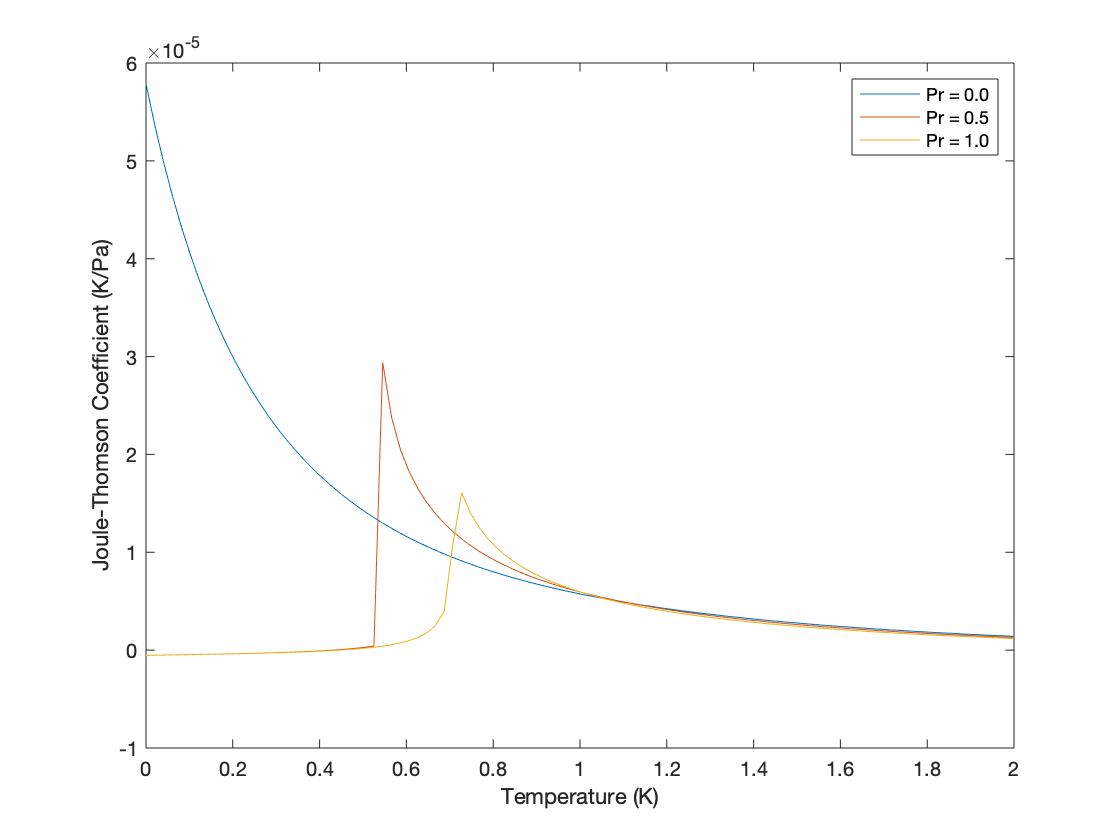

% NO 7 - JT-coefficient vs. T graph
Trange = linspace(Ttriple,2*Tcrit,100);
for j = 1:length(Prange)
    u_jt = zeros(1,length(Trange));
    for i = 1:length(Trange)
        Vreal = max(vpasolve(Prb(Trange(i),V) == Prange(j), V, [0 Inf]));
        if j == 1
            u_jt(i) = (Vreal/cp_P1(i)).*(Trange(i).*alpha_P1(i)-1);
        elseif j == 2
            u_jt(i) = (Vreal/cp_P2(i)).*(Trange(i).*alpha_P2(i) - 1);
        elseif j == 3
            u_jt(i) = (Vreal/cp_P3(i)).*(Trange(i).*alpha_P3(i) - 1);
        end
    end
    if j == 1
        u_jt1 = u_jt;
    elseif j == 2
        u_jt2 = u_jt;
    elseif j == 3
        u_jt3 = u_jt;
    end
end
Trange = linspace(0,2,100);
plot(Trange,u_jt1)
hold on 
plot(Trange,u_jt2)
plot(Trange,u_jt3)

xlabel('Temperature (K)')
ylabel('Joule-Thomson Coefficient (K/Pa)')
%title('Graph of Joule-Thomson coefficient versus temperature')
legend('Pr = 0.0','Pr = 0.5','Pr = 1.0')
hold off